# ICE6: Effects of Additional Dynamics on the Quadratic Response

#### Step Response with Third Pole:

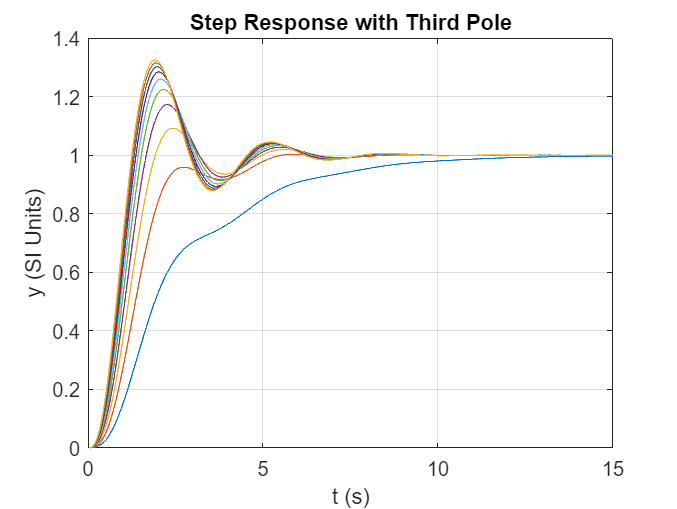

zeta = 0.3; % (Ns)/m
omega_n = 2; % rad/s

Tfinal = 15; % final time
t = (0:0.001:1)*Tfinal; % simulation time
p = (0.2:0.2:2.0)*omega_n; % third pole relative to natural frequency
itot = length(p);

for i = 1:itot % compute step response at each third pole value
    NUM = [omega_n*omega_n*p(i)];
    DEN = [1 (2*zeta*omega_n + p(i)) (omega_n*omega_n + 2*zeta*omega_n*p(i)) (omega_n*omega_n*p(i))];
    DYN = tf(NUM, DEN);
    y = step(DYN,t); % compute step response
    yplot(i,:) = y; % store output in array
end

plot(t, yplot)
grid
title("Step Response with Third Pole")
xlabel("t (s)")
ylabel("y (SI Units)")

#### Step Responses with Zero Factor

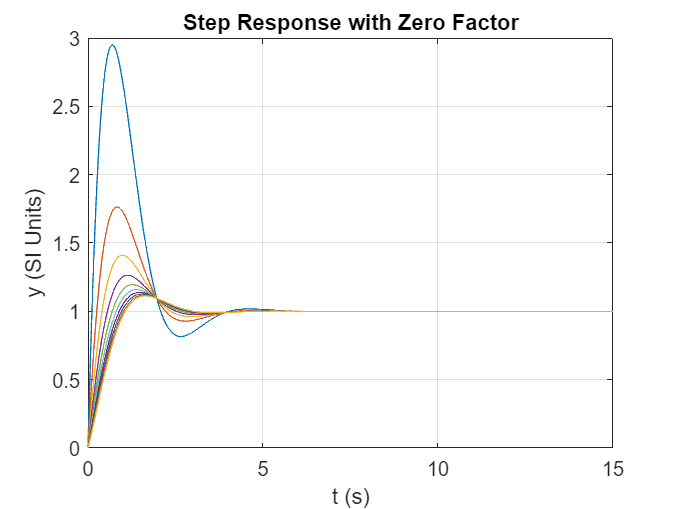

zeta = 0.3; % (Ns)/m
omega_n = 2; % rad/s

Tfinal = 15; % final time
t = (0:0.001:1)*Tfinal; % simulation time
z = (0.2:0.2:2.0)*omega_n; % third pole relative to natural frequency
itot = length(p);

for i = 1:itot % compute step response at each third pole value
    NUM = [omega_n*omega_n omega_n*omega_n*z(i)];
    DEN = [z(i) (2*zeta*omega_n*omega_n*z(i)) (omega_n*omega_n*z(i))];
    DYN = tf(NUM, DEN);
    y = step(DYN,t); % compute step response
    yplot(i,:) = y; % store output in array
end

plot(t, yplot)
grid
title("Step Response with Zero Factor")
xlabel("t (s)")
ylabel("y (SI Units)")